# Inverse Square Law

General model:

     f(x) = a*x^(-2)+b

Coefficients (with 67% confidence bounds):

       a =      0.0372  (0.03185, 0.04255)

       b =   0.0007646  (0.0005611, 0.0009681)

Goodness of fit:

  SSE: 7.956e-07

  R-square: 0.9503

  Adjusted R-square: 0.9462

  RMSE: 0.0002575

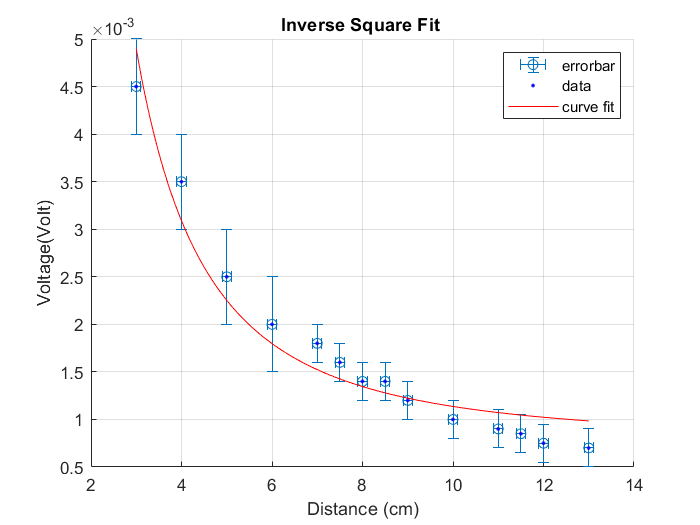

[xData, yData] = prepareCurveData( dist, voltage );
distanceerr=[0.1 0.1 0.1 0.1 0.1 0.1 0.1 0.1 0.1 0.1 0.1 0.1 0.1 0.1];
volterr=[0.5 0.5 0.5 0.5 0.2 0.2 0.2 0.2 0.2 0.2 0.2 0.2 0.2 0.2].*10^(-3);

% Set up fittype and options.
ft = fittype( 'a*x^(-2)+b', 'independent', 'x', 'dependent', 'y' );
opts = fitoptions( 'Method', 'NonlinearLeastSquares' );
opts.Display = 'Off';
opts.StartPoint = [0.957166948242946 0.485375648722841];

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft, opts );
xneg=distanceerr;
xpos=distanceerr;
yneg=volterr;
ypos=yneg;
% Plot fit with data.
figure( 'Name', 'untitled fit 1' );
hold on
errorbar(dist,voltage,yneg,ypos,xneg,xpos,'o')
h = plot( fitresult, xData, yData );

grid on
legend({'errorbar', 'data','curve fit'})
title('Inverse Square Fit ')
xlabel('Distance (cm)')
ylabel('Voltage(Volt)')
hold off

# Log

Linear model Poly1:

     f(x) = p1*x + p2

Coefficients (with 95% confidence bounds):

       p1 =      -1.301  (-1.383, -1.218)

       p2 =      -1.685  (-1.76, -1.611)

Goodness of fit:

  SSE: 0.007912

  R-square: 0.9899

  Adjusted R-square: 0.9891

  RMSE: 0.02568

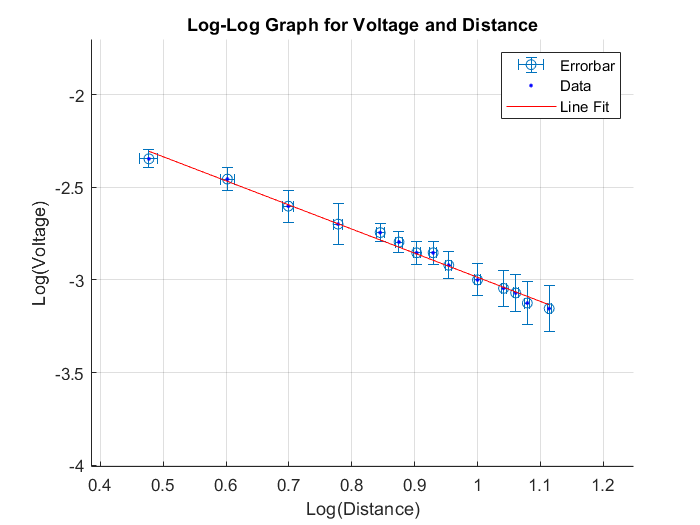

distlogerr=((distanceerr./(log(10)*dist)));
voltlogerr=((volterr./(log(10)*voltage)));

xneg=distlogerr;
xpos=distlogerr;
yneg=voltlogerr;
ypos=yneg;


[xData, yData] = prepareCurveData( logD, logV );

% Set up fittype and options.
ft = fittype( 'poly1' );

% Fit model to data.
[fitresult, gof] = fit( xData, yData, ft );

% Plot fit with data.
figure( 'Name', 'untitled fit 1' );
hold on
errorbar(logD,logV,yneg,ypos,xneg,xpos,'o')
h = plot( fitresult, xData, yData );
xlim([0.385 1.249])
ylim([-4.01 -1.70])
grid on

title('Log-Log Graph for Voltage and Distance')
xlabel('Log(Distance)')
ylabel('Log(Voltage)')
legend({'Errorbar','Data','Line Fit'})
hold off